%% Import and select data & Graph Cumulative Returns to Assets
clear;clc;
cd 'Exercise Set 5'\; 
%Read Portfolio Asset Classes
tblAssets = readtable('ExcerciseSet1_YuanzhanGao_AdityaKumar.xlsx','sheet','Returns'); 

## Question 1

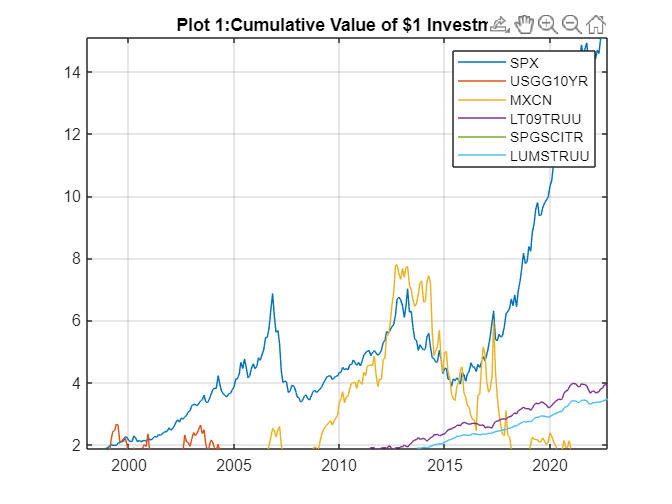

date = datetime(tblAssets.Date); 
% remove NaN rows
date(1, :) = [];
date(361:365, :) = [];
% reverse order to get correct date column
date_ordered = flip(date, 1);
% six indexes:
%1) SPX: S&P 500 - US general stocks performance; best return
%2) USGG10YR: 10YR Treasury
% 9 YR Treasury and MBS are used to hedge the risk
M = [tblAssets.SPXIndex, tblAssets.USGG10YRIndex, tblAssets.MXCNIndex, tblAssets.LT09TRUUIndex, tblAssets.SPGSCITRIndex, tblAssets.LUMSTRUUIndex];
AssetNames = {'SPX', 'USGG10YR', 'MXCN', 'LT09TRUU', 'SPGSCITR', 'LUMSTRUU'}; 
% % Drop unwanted rows and calculate cumulative returns
M(362:366, :) = [];
% set first row equal 0, so 1+0 = 1
M(1, :) = 0;
cum_M = cumprod(1+M);
% remove the first row for unmatched dimensionality
cum_M(1, :) = [];
% plot cumulative return of 1 dollar
figure(1);
plot(date_ordered, cum_M); title('Plot 1:Cumulative Value of $1 Investment');legend('SPX', 'USGG10YR', 'MXCN', 'LT09TRUU', 'SPGSCITR', 'LUMSTRUU');grid on;


% Table for cumulative return and annualized monthly (mean) return
% Question 1 continue
total_month = size(cum_M, 1);
return_table = table([cum_M(360, 1);cum_M(360, 2);cum_M(360, 3);cum_M(360, 4);cum_M(360, 5);cum_M(360, 6);], ...
    [cum_M(360, 1)^(12/total_month)-1;cum_M(360, 2)^(12/total_month)-1;cum_M(360, 3)^(12/total_month)-1;cum_M(360, 4)^(12/total_month)-1;cum_M(360, 5)^(12/total_month)-1;cum_M(360, 6)^(12/total_month)-1;], ...
    'RowNames', AssetNames, ...
    'VariableNames',{'Cumulative Dollar Return($)','Annualized Mean Return(%)'});

disp(return_table);

                Cumulative Dollar Return($)    Annualized Mean Return(%)
                ___________________________    _________________________

    SPX                    15.808                      0.096384         
    USGG10YR              0.57954                      -0.01802         
    MXCN                   1.2983                       0.00874         
    LT09TRUU               4.1879                      0.048898         
    SPGSCITR               1.4607                       0.01271         
    LUMSTRUU               3.5671                      0.043303         



## 2.a.	Set Portfolio Optimization Constraints & Options

% Construct the variance/Covariance matrix

%r remove first row of M (currently 0 which is added for 1$ cum return
%calculation)
if size(M, 1) == 361
    M(1, :) = [];
end

T = size(M, 1);
for t = 36:T
    V = cov(M(t-35:t,:)); 
    Vcov(:,:,t) = V; Vcond(t) = cond(V); 
end

% calculate monthly mean return (not annualized, because I don't want to:)
mean_return = (prod(1+M).^(1/T)-1);

% Set up conditions for quadratic programming
nAssets = size(M, 2); r = 0.0055;     % number of assets and desired return (use monthly return here)
Aeq = ones(1,nAssets); beq = 1;              % equality Aeq*x = beq (all sum to 1)
Aineq = -mean_return; bineq = -r;            % inequality Aineq*x <= bineq
% why negative:
% since quadprog's 3rd and 4th parameter only sets up the constraint as
% A*x < b, to reach a return greater than designated r, the return needs
% to be greater than r in absolute value, or less than -r when the return
% and r are both positive.


lb = zeros(nAssets,1); ub = ones(nAssets,1); % bounds lb <= x <= ub (no shorting)
c = zeros(nAssets,1);                        % objective has no linear term; set it to zero
% Select Options for Quadprog
options = optimset('Algorithm','interior-point-convex');
options = optimset(options,'Display','off','TolFun',1e-10);

## Optimize three base and three stress cases

dateStr = datestr(date);
n = strmatch('30-Jul-2010',dateStr,'exact');
% Base case:  
Vbase = cov(M);  % Average through whole sample
wmvBase = quadprog(Vbase,c,[],[],Aeq,beq,[],[],[],options); % allow shorting
wBase = quadprog(Vbase,c,Aineq,bineq,Aeq,beq,lb,ub,[],options); % greater or equal than target return; does not allow shorting
wrpBase = riskBudgetingPortfolio(Vbase);

% Stress case
Vstress = Vcov(:,:,n);  % n = location for '30-Jul-2010'
wmvStress = quadprog(Vstress,c,[],[],Aeq,beq,[],[],[],options); 
wStress = quadprog(Vstress,c,Aineq,bineq,Aeq,beq,lb,ub,[],options);
wrpStress = riskBudgetingPortfolio(Vstress);

## 2. Continue: Table Result

## 2.a. Portofolio Weights

PortWts = table(wmvBase, wmvStress,wBase,wStress,wrpBase,wrpStress,'RowNames',AssetNames);
disp("Portofolio Weights");

Portofolio Weights


disp(PortWts);

                 wmvBase      wmvStress      wBase        wStress      wrpBase     wrpStress
                __________    _________    __________    __________    ________    _________

    SPX         -0.0086748     0.014877       0.40787       0.40787     0.05299    0.034393 
    USGG10YR        0.1008      0.08139    2.6688e-08    5.1809e-09     0.10114    0.084764 
    MXCN        -0.0018284    -0.011656    3.6072e-12    1.4674e-11    0.026759    0.018398 
    LT09TRUU       0.29892      0.34193       0.59213       0.59213     0.43269     0.51567 
    SPGSCITR    -0.0037402    -0.013944    7.4297e-12    2.5217e-11    0.039523    0.022866 
    LUMSTRUU       0.61453      0.58741   

disp("In the minimal variance portofolio for both base and stress cases, we find that we are shorting ");

In the minimal variance portofolio for both base and stress cases, we find that we are shorting 


## 2.b. Portofolio month Returns

% Expected Return for each of the portofolio
% we use the mean return of the portofolio 
%% MONTHLY RETURN!! (SINCE mean_return is the average monthlized return over the entire 30 years span)
Rmv_base =  mean_return * wmvBase;
Rmv_stress = mean_return* wmvStress;
R_base = mean_return * wBase;
R_stress = mean_return* wStress;
Rrp_base = mean_return * wrpBase;
Rrp_stress = mean_return * wrpStress;
PortRet = table([Rmv_base; R_base; Rrp_base], [Rmv_stress;R_stress;Rrp_stress],'RowNames',{'mv','targRet','riskparity'},'VariableNames',{'Base','Stress'});
disp(PortRet);

                    Base        Stress  
                  _________    _________

    mv            0.0031416    0.0034099
    targRet          0.0055       0.0055
    riskparity    0.0032682    0.0033757



disp("The target return ");

The target return 


## 2.c. portofolio risks

riskBase = round(sqrt(wBase'*(12*Vbase)*wBase),3);
riskStress = round(sqrt(wStress'*(12*Vstress)*wStress),3);

riskParityBase = round(sqrt(wrpBase'*(12*Vbase)*wrpBase),3);
riskParityStress = round(sqrt(wrpStress'*(12*Vstress)*wrpStress),3);

riskScenarios = table(riskBase,riskStress,riskParityBase,riskParityStress, ...
    'VariableNames',{'MaxSharpeBase','MaxSharpeStress','RiskParityBase','RiskParityStress'});
disp(riskScenarios);

    MaxSharpeBase    MaxSharpeStress    RiskParityBase    RiskParityStress
    _____________    _______________    ______________    ________________

        0.068             0.046             0.029              0.016      



## 2.d. MCR

MCR = table(round(12*Vbase*wBase/riskBase,3), round(12*Vstress*wStress/riskStress,3), round(12*Vbase*wrpBase/riskParityBase,3), round(12*Vstress*wrpStress/riskParityStress,3),'VariableNames', {'MCRBase', 'MCRStress', 'MCRRPBase', 'MCRRPStress'},'RowNames', AssetNames);
disp(MCR);

                MCRBase    MCRStress    MCRRPBase    MCRRPStress
                _______    _________    _________    ___________

    SPX          0.125       0.101         0.09         0.076   
    USGG10YR    -0.108      -0.039        0.047         0.031   
    MXCN         0.124       0.136        0.179         0.141   
    LT09TRUU     0.028       0.008        0.011         0.005   
    SPGSCITR     0.042       0.111        0.121         0.114   
    LUMSTRUU     0.017       0.008        0.014         0.008   



## 2.e. Risk Attribution/Budget

riskBudget_Base = round((12*Vbase*wBase/riskBase).*wBase,3);
riskBudget_Stress = round((12*Vstress*wStress/riskStress).*wStress,3);
riskBudget_rp_Base = round((12*Vbase*wrpBase/riskParityBase).*wrpBase,3);
riskBudget_rp_Stress = round((12*Vstress*wrpStress/riskParityStress).*wrpStress,3);
RiskBudget = table(riskBudget_Base, riskBudget_Stress, riskBudget_rp_Base, riskBudget_rp_Stress, 'VariableNames', {'RiskBudgetBase', 'RiskBudgetStress', 'RiskBudgetRPBase', 'RiskBudgetRPStress'}, 'RowNames',AssetNames);
disp(RiskBudget);

                RiskBudgetBase    RiskBudgetStress    RiskBudgetRPBase    RiskBudgetRPStress
                ______________    ________________    ________________    __________________

    SPX             0.051              0.041               0.005                0.003       
    USGG10YR            0                  0               0.005                0.003       
    MXCN                0                  0               0.005                0.003       
    LT09TRUU        0.016              0.005               0.005                0.003       
    SPGSCITR            0                  0               0.005                0.003       
    LUMSTRUU            0                  0               0.005                0.003       



## 3. Estimate VaR at the 1-percent level for each of the six portfolios.  Tell me exactly what these mean for the three portfolios under both the  Base and Stress cases.

VaR_01 = ((1+[R_base, R_stress, Rrp_base, Rrp_stress]).^12 -1) + norminv([0.005, 0.995])'*[table2array(riskScenarios)];
Var01_table = array2table(VaR_01, 'RowNames',{'Upper Bound', 'Lower Bound'}, 'VariableNames', {'R_Base', 'R_Stress', 'R_rp_Base', 'R_rp_Stress'});
disp("We are 99% confident that the annualized expected return for each portofolio is as follows:");

We are 99% confident that the annualized expected return for each portofolio is as follows:


disp(Var01_table);

                    R_Base     R_Stress     R_rp_Base    R_rp_Stress
                   ________    _________    _________    ___________

    Upper Bound    -0.10712    -0.050455    -0.034767    5.5749e-05 
    Lower Bound     0.24319      0.18652      0.11463      0.082482 



disp("For the target return portofolio in base case, we are 99% confident that the annualized return falls between -10.7% and 24.3%.");

For the target return portofolio in base case, we are 99% confident that the annualized return falls between -10.7% and 24.3%.


disp("For the target return portofolio in stress case, we are 99% confident that the annualized return falls between -5.04% and 18.7%.");

For the target return portofolio in stress case, we are 99% confident that the annualized return falls between -5.04% and 18.7%.


disp("For the risk parity return portofolio in base case, we are 99% confident that the annualized return falls between -3.48% and 11.5%.");

For the risk parity return portofolio in base case, we are 99% confident that the annualized return falls between -3.48% and 11.5%.


disp("For the risk parity return portofolio in stress case, we are 99% confident that the annualized return falls between 0.0057% and 8.25%.");

For the risk parity return portofolio in stress case, we are 99% confident that the annualized return falls between 0.0057% and 8.25%.


## Question 4

% 4.a
%Base case target Return
R_Base_total = M*wBase;
% Read in BlackRock factor
Factors = readtable('ExcerciseSet1_YuanzhanGao_AdityaKumar.xlsx','sheet','BLK_AQR');
dateFactor = datetime(Factors.DATE);
BR_factors = [Factors.RealRates, Factors.Inflation, Factors.Credit, Factors.Economic, Factors.EmergingMarkets, Factors.Liquidity];
[T,k]= size(BR_factors); 

% Trim the BR_factors matrix to date we are interested in
% StartDate is Jan-93
start_date = strmatch('31-Jan-1993', datestr(dateFactor), 'exact');
% EndDate is Dec-22, which the BR_factors do not have in the dataset; we
% will just use Nov-22 and drop the first row of target-return which is for
% Dec-2022
BR_factors_trimmed = BR_factors(start_date:end, :);

% Reverse the target return matrix R_Base_total to match the date sequence
% now Dec-2022 is at the bottom, correponding to the dateFactor
R_Base_t_reversed = flip(R_Base_total, 1);

% Find Betas for BlackRock factors with a 36-months trailing
b = zeros(size(BR_factors_trimmed,1), 7); % create an empty matrix to store betas N rows x cols=(intercept and k factors). 
A = zeros(size(BR_factors_trimmed,1), 8); % create an empty matrix to store factor attributionex N rows x  cols

for t = 36:size(BR_factors_trimmed,1) % == 359
    LM = fitlm(BR_factors_trimmed(t-35:t,:),R_Base_t_reversed(t-35:t)); 
    b(t,:) = (LM.Coefficients.Estimate)';
    A(t,:) = [R_Base_t_reversed(t)-b(t,1)-BR_factors_trimmed(t,:)*b(t,2:end)', b(t,1), b(t,2:end).*BR_factors_trimmed(t,:)];
end


## 4.a. Plot betas with respect to time

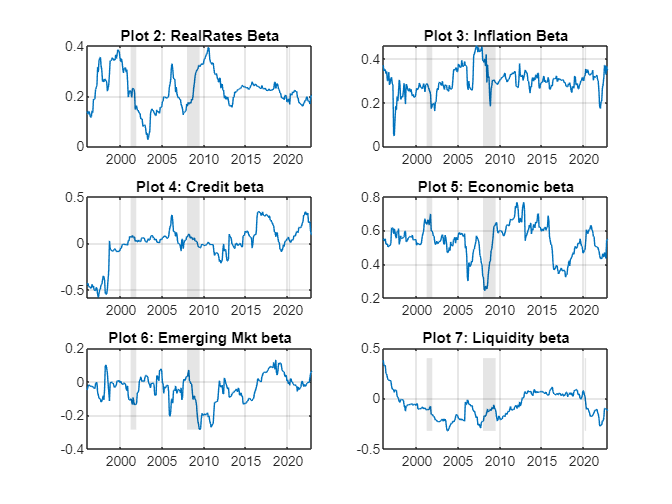

% 4.a.
% Beta exposures first 
figure(2);
subplot(3,2,1); plot(dateFactor(start_date+35:end),b(36:end,2)); recessionplot; title('Plot 2: RealRates Beta'); grid on; 
subplot(3,2,2); plot(dateFactor(start_date+35:end),b(36:end,3)); recessionplot; title('Plot 3: Inflation Beta'); grid on; 
subplot(3,2,3); plot(dateFactor(start_date+35:end),b(36:end,4)); recessionplot; title('Plot 4: Credit beta'); grid on; 
subplot(3,2,4); plot(dateFactor(start_date+35:end),b(36:end,5)); recessionplot; title('Plot 5: Economic beta'); grid on; 
subplot(3,2,5); plot(dateFactor(start_date+35:end),b(36:end,6)); recessionplot; title('Plot 6: Emerging Mkt beta'); grid on; 
subplot(3,2,6); plot(dateFactor(start_date+35:end),b(36:end,7)); recessionplot; title('Plot 7: Liquidity beta'); grid on;

## 4.b. Monthly Return Attribution

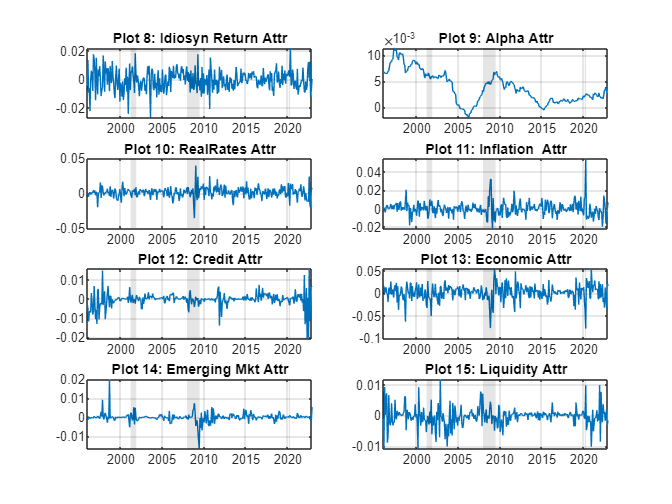

% 4.b.
figure(3);
subplot(4,2,1); plot(dateFactor(start_date+35:end),A(36:end,1)); recessionplot; title('Plot 8: Idiosyn Return Attr'); grid on; 
subplot(4,2,2); plot(dateFactor(start_date+35:end),A(36:end,2)); recessionplot; title('Plot 9: Alpha Attr'); grid on; 
subplot(4,2,3); plot(dateFactor(start_date+35:end),A(36:end,3)); recessionplot; title('Plot 10: RealRates Attr'); grid on; 
subplot(4,2,4); plot(dateFactor(start_date+35:end),A(36:end,4)); recessionplot; title('Plot 11: Inflation  Attr'); grid on; 
subplot(4,2,5); plot(dateFactor(start_date+35:end),A(36:end,5)); recessionplot; title('Plot 12: Credit Attr'); grid on; 
subplot(4,2,6); plot(dateFactor(start_date+35:end),A(36:end,6)); recessionplot; title('Plot 13: Economic Attr'); grid on; 
subplot(4,2,7); plot(dateFactor(start_date+35:end),A(36:end,7)); recessionplot; title('Plot 14: Emerging Mkt Attr'); grid on; 
subplot(4,2,8); plot(dateFactor(start_date+35:end),A(36:end,8)); recessionplot; title('Plot 15: Liquidity Attr'); grid on;